Get operating point

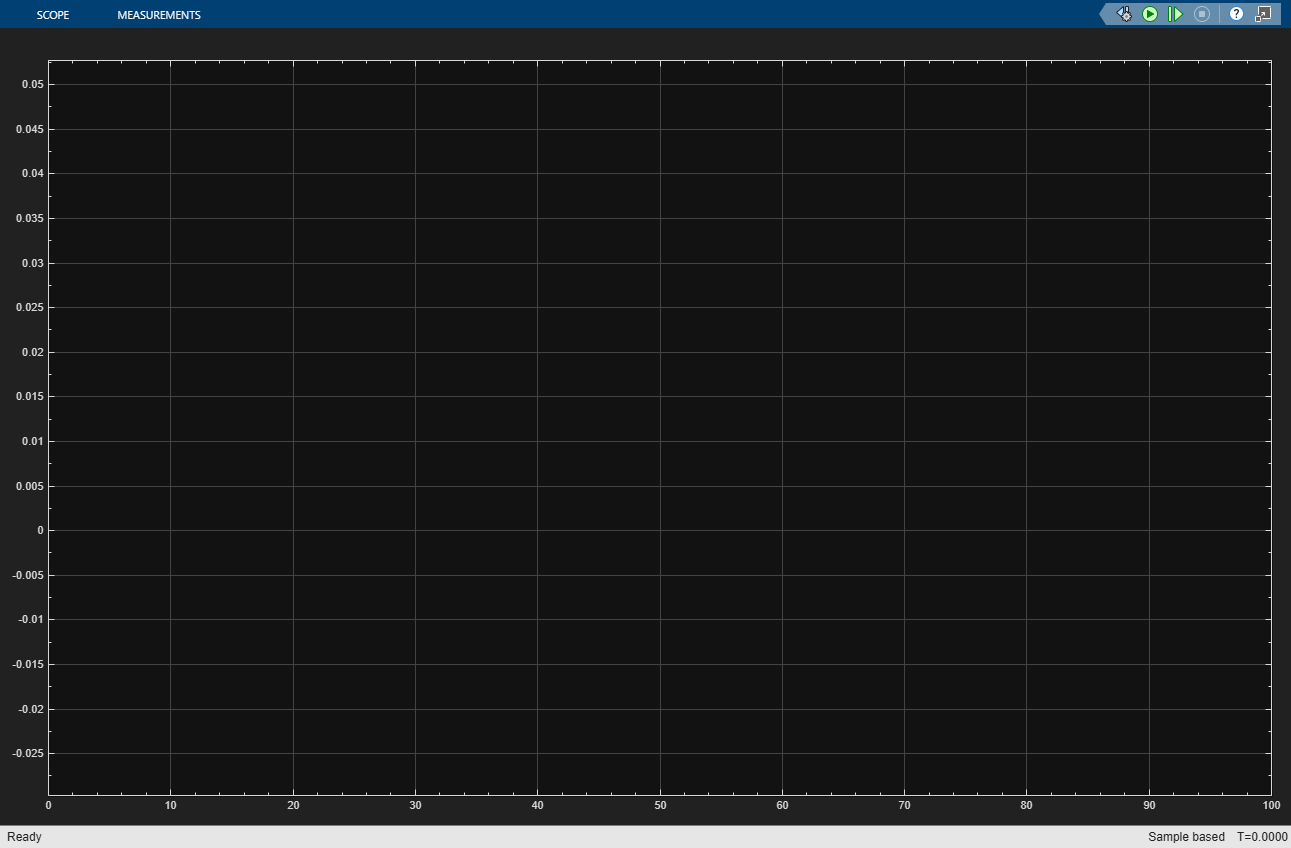

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(6.01783e-01) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_thrus_resp_bot
(3.29583e-11) main_to_linearize/Drone Dynamics/Actuator Dynamics/motor_thrus_resp_bot


% run trimming.m file
run('linear_analysis/trimming.m')

Linearize model from rate input to rate output

mdl = 'main_to_linearize'

mdl = 'main_to_linearize'

io(1) = linio('main_to_linearize/att_control/pitch_rate', 1, 'input')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y


io(2) = linio('main_to_linearize/Drone Dynamics/w_b_comp', 2, 'output')


1x2 vector of Linearization IOs: 
--------------------------
1. Linearization input perturbation located at the following signal:
- Block: main_to_linearize/att_control/pitch_rate
- Port: 1
2. Linearization output measurement located at the following signal:
- Block: main_to_linearize/Drone Dynamics/w_b_comp
- Port: 2
- Signal Name: w_y



G_rate =
 
  A = 
                    p,q,r (1)     p,q,r (2)  bx_actuator_  bx_actuator_  by_actuator_  by_actuator_
   p,q,r (1)                0     1.102e-33        -224.1     1.831e+04             0             0
   p,q,r (2)       -1.102e-33             0             0             0        -224.1     1.831e+04
   bx_actuator_             0             0        -13.13        -72.64             0             0
   bx_actuator_             0             0             1             0             0             0
   by_actuator_             0             0             0             0        -13.13        -72.64
   by_actuator_             0             0             0             0             1             0
 
  B = 
                 pitch_rate
   p,q,r (1)              0
   p,q,r (2)              0
   bx_actuator_   1.267e-19
   bx_actuator_           0
   by_actuator_    0.002069
   by_actuator_           0
 
  C = 
           p,q,r (1)     p,q,r (2)  bx_actuator_  bx_actuator_  by_


G_rate = linearize(mdl, io, op)

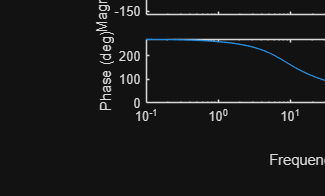

bode(G_rate)

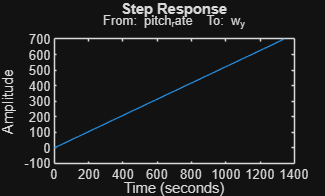

step(G_rate)

% [num, den] = ss2tf(G_rate.A, G_rate.B, G_rate.C, G_rate.D)
% s = tf('s')
% G_rate_tf = tf(num, den) * exp(-0.2*s)
% [A,B,C,D] = tf2ss(G_rate_tf.Numerator{1}, G_rate_tf.Denominator{1})
% G_rate = ss(A,B,C,D)

Control System Designer

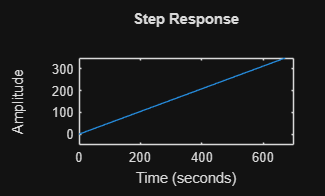

step(G_rate)